clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Import

% Load directory with the raw files
Dir.LDir = dir('data/raw/20230622_Qband/*.DTA');

Measurements not to be saved: measurement 01 is a wide scan and measurement 13 (the last one) is calibration

**Field correction is taken into consideration!!**

for icw = 2:numel(Dir.LDir) - 1
    LPath_ = [Dir.LDir(icw).folder, '\', Dir.LDir(icw).name];
    [cw(icw).xRaw, y_, cw(icw).Params] = eprload(LPath_);
    % Field correction
    cw(icw).x = cw(icw).xRaw/10 + 0.2905; % mT
    cw(icw).yRaw = y_{1, 1} + 1i*y_{1, 2};    
    cw(icw).Title = Dir.LDir(icw).name;
end
cw(1) = [];
ncw = numel(cw);

# Subtract baseline

Subtract linear baseline

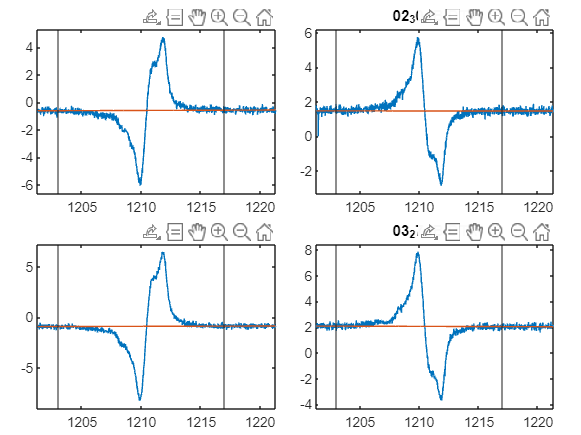

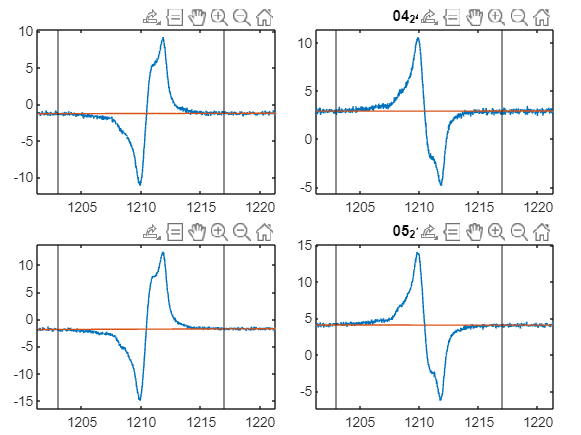

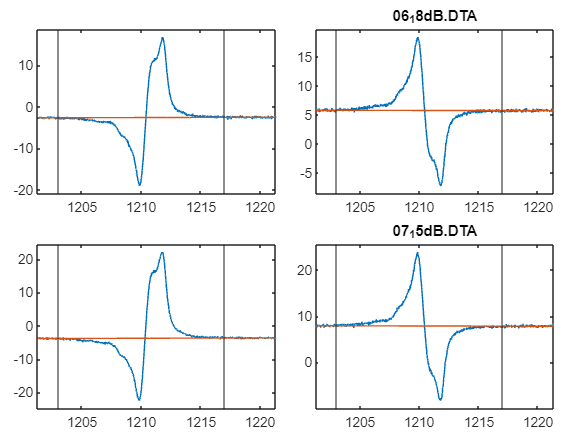

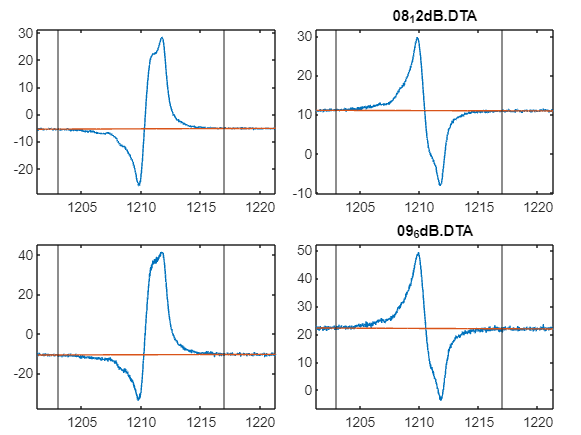

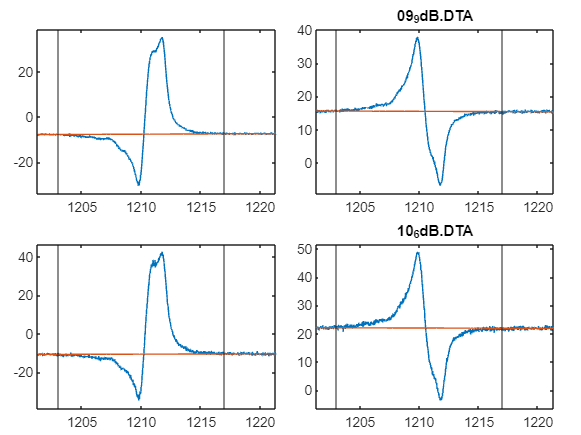

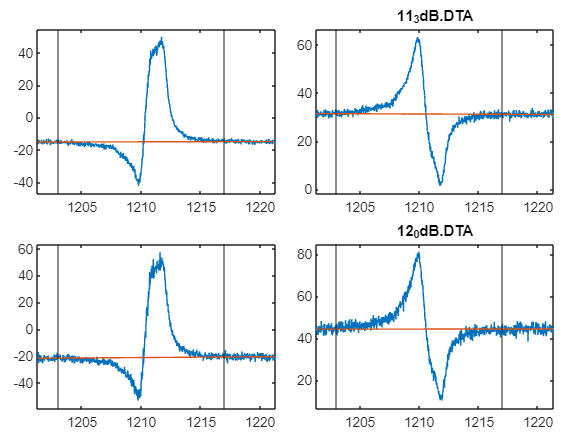

Opt.Bl.Order = 1;
Opt.Bl.Range = [0 1203; 1217 10000];

for icw = 1:ncw
    cw(icw).BlOpt = Opt.Bl;
    % y1 is the spectrum baseline corrected but not phase corrected
    [cw(icw).y1, cw(icw).Bl] = ...
        subtractBaseline(cw(icw).x, cw(icw).yRaw, Opt.Bl);
end

nFig = ncw/2;
for iFig = 1:nFig
    figure();
    tiledlayout(ncw/(nFig), 2, 'TileSpacing', 'compact', 'Padding', 'compact')
        for icw = (iFig-1)*ncw/nFig + 1:iFig*ncw/nFig; nexttile()
            plot(cw(icw).x, real(cw(icw).yRaw), cw(icw).x, real(cw(icw).Bl));
            xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(real(cw(icw).yRaw), 0.05));
            xline(Opt.Bl.Range(1,2)); xline(Opt.Bl.Range(2,1));
             %xline(Opt.Bl.Range(2,2)); xline(Opt.Bl.Range(3,1));
            nexttile()
            plot(cw(icw).x, imag(cw(icw).yRaw), cw(icw).x, imag(cw(icw).Bl)); 
            xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(imag(cw(icw).yRaw), 0.05));
            xline(Opt.Bl.Range(1,2)); xline(Opt.Bl.Range(2,1));
             %xline(Opt.Bl.Range(2,2)); xline(Opt.Bl.Range(3,1));
            title(cw(icw).Title)
        end
end

# Correct phase

- Why has the signal in the 0deg channel an uncommon phase? First it goes down and then it goes up. It happens also with the calibration N@C60 sample.

- The phase to minimize the second channel is around 30deg. A signal appears in the second channel for mwpw > 0.4 mW (15dB).

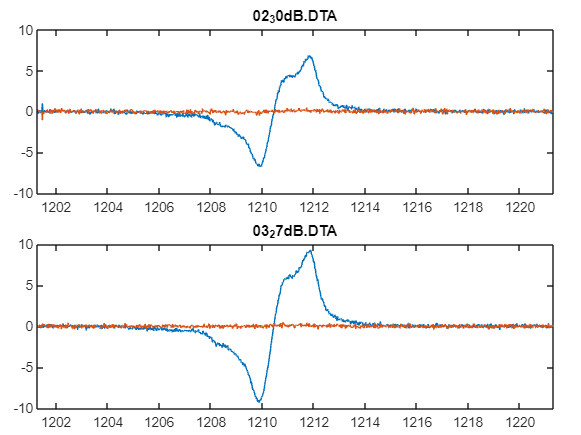

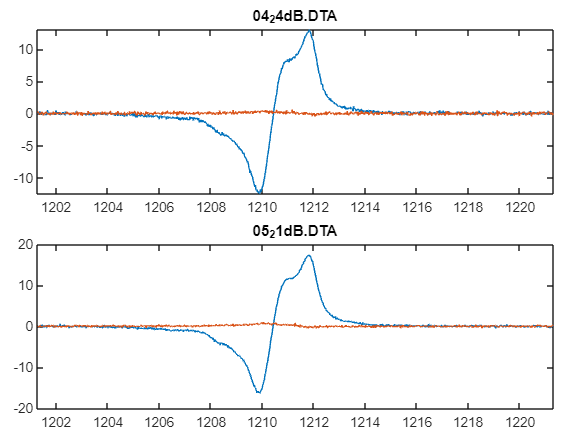

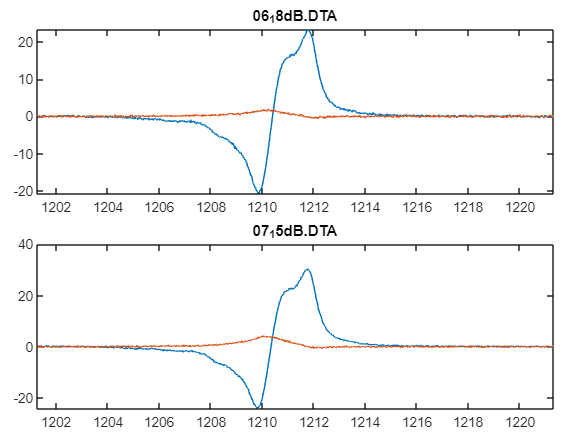

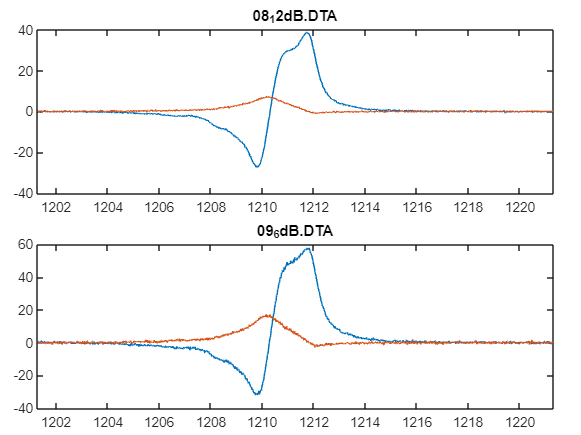

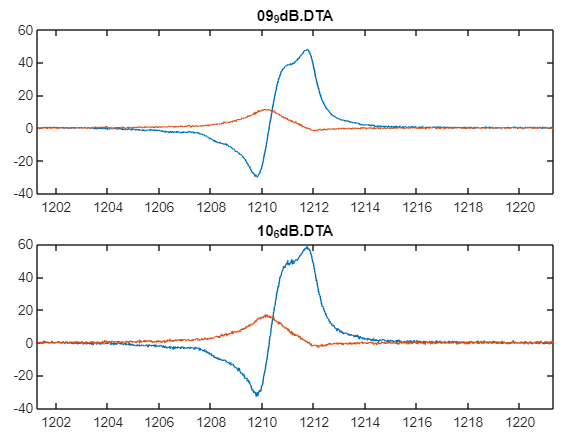

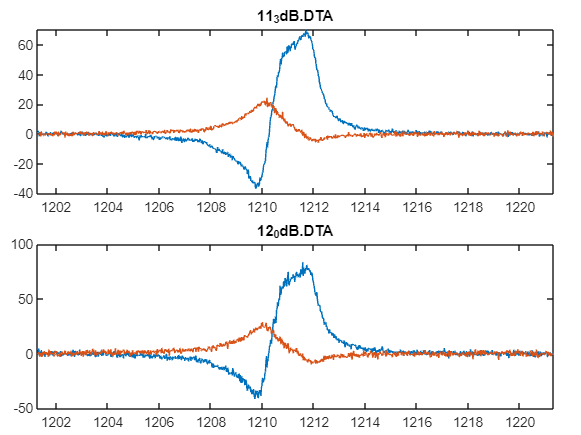

for icw = 1:ncw
    % y2 is the spectrum baseline and phase corrected
    [cw(icw).y2, cw(icw).Phase] = correctPhase(cw(icw).y1, 'Maximum');
%     cw(icw).y = real(cw(icw).y2);
end

for iFig = 1:nFig
    figure();
    tiledlayout(ncw/(nFig), 1, 'TileSpacing', 'compact', 'Padding', 'compact')
    for icw = (iFig-1)*ncw/nFig + 1:iFig*ncw/nFig; nexttile()
        %plot(cw(icw).x, real(cw(icw).y2 - mean(real(cw(icw).y2))), cw(icw).x, imag(cw(icw).y2) - mean(imag(cw(icw).y2)));
        plot(cw(icw).x, real(cw(icw).y2), cw(icw).x, imag(cw(icw).y2));
        xlim(setAxLim(cw(icw).x, 0)); % ylim(setAxLim(real(cw(icw).y2), 0.2));
        title(cw(icw).Title)
    end
end

# Manual phase correction

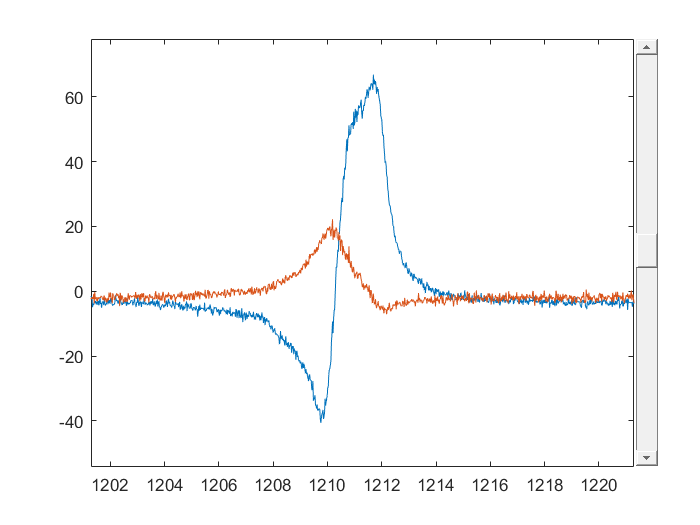

ICW = 11;
mpcModel = @(y2, p) (y2 - mean(y2)) * exp(1i*p*pi/180);
mpcArray = zeros(numel(cw(ICW).x), 181); % Array of phase corrected data
mpc = {mpcArray, mpcArray, mpcArray, mpcArray};
mpcArray_ = mpcArray;
for iP = -90:90
    mpcArray_(:,90 + iP + 1) = mpcModel(cw(ICW).y2, iP*1);
end
mpc{1} = mpcArray_;

figure()
% Phase at which the scrollable starts. Set p0 = 0 if the phase
% correction was already done
p0 = 0;
h1 = ScrollableAxes('Index', 91 + 1 + p0); 
plot(h1, cw(ICW).x, -90:90, real(mpc{1, 1}));
hold on
plot(h1, cw(ICW).x, -90:90, imag(mpc{1, 1}));

# Save into mat

**For now, I will save the 0deg channel after baseline correction only and with a change of sign (that is -y1) as the y array. **This might be changed in the future when the phase correction is optimized.

% Insert path where data is saved or will be saved
Dir.SPath = 'data/processed/s20230622_sample4_Qband_mwpw.mat';

for icw = 1:ncw
    cw(icw).y = -real(cw(icw).y1);
end

if ~isfile(Dir.SPath)
    Title = '2023-06-22 cwEPR Sijia sample 4 Qband mwpw';
    save(Dir.SPath, 'cw', 'Title');
else
    load(Dir.SPath)
end